clear all, close all, clc

## Example 2.2

Let's assign the probability values

pa = 0.01;          % probab' of a
pb = 0.1;
pc = pb;
pd = pb; pe = pb;

Let's define other variables

du = pb *pc;        % bi-product
tr = pb*pc*pd;      % tri-prodduct
qd = pb*pc*pd*pe    % quad-product

qd = 1.0000e-04

 
$${\left[A+BD+BE+CD+CE\right]}$$
 
$$-{\left[ABD+ABE+ACD+ACE+BDE+BDC+2BDCE+BEC+CDE\right]}$$



$$+{\left[ADBE+ABDC+2ABDCE+ABEC+ACDE+4BECD\right]}$$
 
$$-\left\lbrack 4ABCDE+BDEC\right\rbrack$$

$$+\left\lbrack ABDEC\right\rbrack$$


T1 = pa + 4*du

T1 = 0.0500

T2 = pa*4*du + 4*tr +2*qd

T2 = 0.0046

T3 = pa*4*tr +2*pa *qd + 4*qd

T3 = 4.4200e-04

T4 = qd + 4*pa*qd

T4 = 1.0400e-04

T5 = pa*qd

T5 = 1.0000e-06

Then, the results become

pH = T1 - T2 + T3 - T4 + T5

pH = 0.0457

## Example 2.3

Given,

p = 0.5;            % probab' of random variable
p_k1 = p;
p_k2 = 1-p;
k1 = 1;             % function value
k2 = 0;

Now we have

m = p_k1 *k1 + p_k2 *k2         % mean

m = 0.5000

For variance,

vr = (k1-m)^2 *p_k1 + (k2-m)^2 *p_k2          % variance 

vr = 0.2500

## Example 2.3-2

Given,

pf = 1e-4;           % fail probab'
ps = 1-pf;           % survaiing probab
N = 20*52*6        % switch usage, 6 y

N = 6240

As fail occurs at very last attempt-

M = 1;              % no. of failure

So, at the end of 6y period, the probab' of switch failing- at very last

$P_s =p_s^{n-m}$, probability that it survives (n - m) trials

$P_f =p_f^m$, probability that it fails at m-th trial

%         C = nchoosek(N,M);
P_N = pf^M *ps^(N-M)

P_N = 5.3583e-05

### (b)

So, probability of exactly 1 failure could be determined-


$$P_N {\left(M\right)}={}^N_{\ }{C_M }F^M {\bar{\;F\;} }^{N-M}$$


    C = nchoosek(N,M);
P_N1 = C *pf^M *ps^(N-M)

P_N1 = 0.3344

## Example 2.4

n = 1000;       % no. of attempt
m = 2;          % no. of failure
F = 1e-4;       % failure probability
Fb = 1-F;       % not failure

Now, we have: $P_N {\left(M\right)}={}^N_{\ }{C_M }F^M {\bar{\;F\;} }^{N-M}$

    nCm = nchoosek(n,m);
P = nCm *F^m *Fb^(n-m)

P = 0.0045

Now, for failing two or more than that is-


$$P_N {\left(>M\right)}\;=1-\sum_0^M P_N \left(M\right)$$


Now, probability of failing 0 times

nC0 = nchoosek(n,0);
P_0 = nC0 *F^0 *Fb^(n-0);

Failing 1 times

nC1 = nchoosek(n,1);
P_1 = nC1 *F^1 *Fb^(n-1);

So, the probability of failing 2 or more-

P_2m = 1 - (P_0 + P_1)

P_2m = 0.0047

Extension: What's the probability for failing 4 times. Less than 4 times. 

## Example 2.5

n = 4;          % no. of machine
% m = 1;          % no. of failure
F = 0.02;       % failure probability
Fb = 1-F;       % not failure

Let's count the failure probab's component wise using binomial dist.


$$P_N \left(m\right)={}^N_{\ }{C_M \;}F^M \;F^{\left(N-M\right)}$$


nC0 = nchoosek(n,0);
P_0 = nC0 *F^0 *Fb^(n-0)    % no comp. failure

P_0 = 0.9224


nC1 = nchoosek(n,1);
P_1 = nC1 *F^1 *Fb^(n-1)    % 1 comp. failure

P_1 = 0.0753

So, probability of total failure- equal or more than 2 component failure

P_2m = 1 - (P_0 + P_1)

P_2m = 0.0023

## Example 2.6

N = 200;            % no. of assemblies
n = 3;              % failing assemblies
F = 0.01;           % failure probab.
mu = N*F;           % mean no. of failure; m, from binomial dist.

Now, let's use Poission dist. for probabilities-


$$P{\left(n\right)}=\frac{e^{-\mu } \mu^n }{n!}$$


So, let's find exactly 3 failure by means of Poisson dist-

fn = factorial(n);
P_n = exp(-mu)*mu^n /fn

P_n = 0.1804

*Let's do via binomial dist.*

n = 200;
m = 3;
F = 0.01;           % failure probab.
Fb = 1-F;

Now, we get for exactly 3 failures

nCm = nchoosek(n,m);
P_1 = nCm *F^m *Fb^(n-m)

P_1 = 0.1814

The two results are fairly similar

## **Example 2.7**

mu = 1000;          % mean
vr = 2500;          % variance
sg = sqrt(vr);      % StD
x1 = mu*0.9;
x2 = mu*1.1;

Let's find the x_h (z-score)


$$\hat{x} =\frac{x-m}{\sigma }$$


x_h1 = (x1-mu)/sg

x_h1 = -2

x_h2 = (x2-mu)/sg

x_h2 = 2

Then, we have for CDF for Normal Distribution


$$\phi {\left(x\right)}=\frac{1}{\sqrt{2\pi }}\exp {\left[-\frac{{\hat{x} }^2 }{2}\right]}=\frac{1}{2}\left\lbrack 1+\textrm{erf}\;\hat{\;\frac{x}{\sqrt{2}}} \right\rbrack$$


ph1 = 0.5*(1 + erf(x_h1 /sqrt(2)) )

ph1 = 0.0228

ph2 = 0.5*(1 + erf(x_h2 /sqrt(2)) )

ph2 = 0.9772

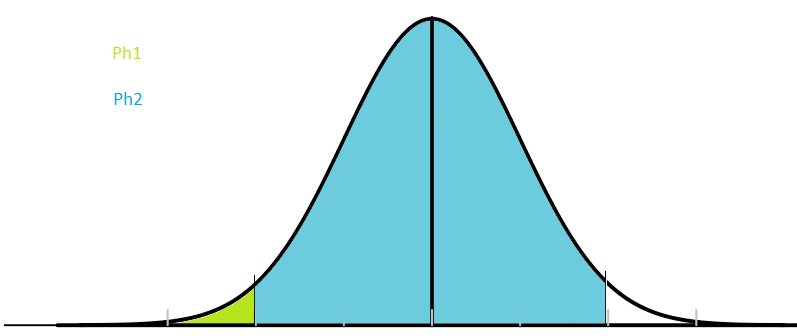 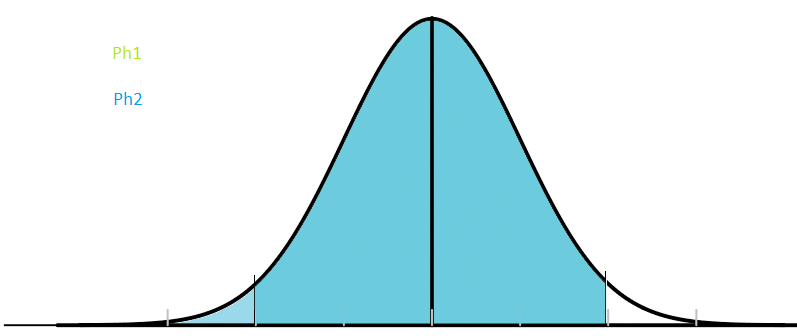

So, the probability is, presented by the colored area here. And the rejected ones are-

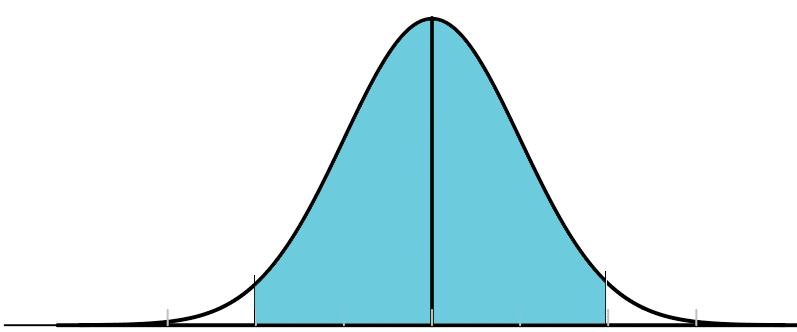

p = ph1 + (1- ph2)          % rejecteds probab'

p = 0.0455

## Example 2.8

lam = 1e-4;         % failure rate
F = 0.2;            % failure probab'

syms t a 
lam_1 = 0;
lam_2 = lam; 
lam_3 = lam *exp(0.002*t -2);

Thence, weh have:


$$R{\left(t\right)}=\exp {\left(\int_0^t \lambda {\left(t\right)}dt\right)}$$


R_1 = exp(-int(lam_1, 0,t));   % exp, min, max
R_2 = exp(-int(lam_2, 10,t))

$$R\_2 = {\mathrm{e}}^{\frac{1}{1000}-\frac{t}{10000}}$$

R_3 = exp(-int(lam_3, 1000,t));

R = 1 - F          % reliability

R = 0.8000

Now, let's find the value of T

eqn3 = R_3 == R;
T3 = solve(eqn3, t);
T3 = double(T3)

T3 = 1.8490e+03

And then,

eqn2 = R_2 == R;
T2 = solve(eqn2, t);
T2 = double(T2)

T2 = 2.2414e+03

## **Example 2.9**

lam = 1e-2;         % ; y^-1
tau = 0.5;          % delay time; y
T = 5;              % total operating time; y
t = T-tau;          % time in corrosion
alf = 2;

Let's find the frequency of incident by checking-

lm_t = lam *t

lm_t = 0.0450

--this is << 1, so, it could be termed as rare event

From rare event approximation, we'll find the cumulitive distribution of 

F = (lm_t)^alf /alf *( 1 - alf*lm_t /(alf + 1) )

F = 9.8213e-04

Now, let's find the MTTF, as it is $\gamma \;$distribution-


$$\textrm{MTTF}=\tau +\frac{\;\alpha }{\lambda \;}$$


MTTF = tau + alf/lam      % year

MTTF = 200.5000